# Distance algorithm evaluation

This document contains statistics used for evaluating the ICO and PID controller to keep a fixed distance to the fence. 

clear; clc;

## One ICO controller

### Load data:

folder = 'eval_ico'; %'../docker/ros-fence-inspection/assets/eval_ico';

ico_data = load_n_process(folder);

### Normal distribution test:

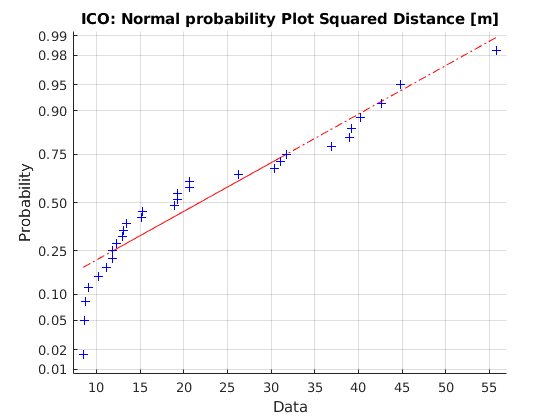

% Squared dist
figure(1)
normplot(ico_data(:,1))
title('ICO: Normal probability Plot Squared Distance [m]')

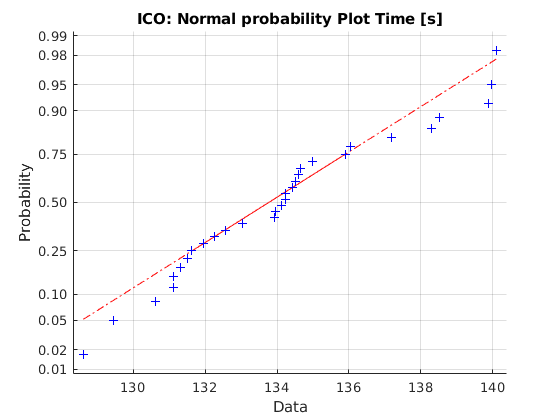


% Lap time 
figure(2)
normplot(ico_data(:,2))
title('ICO: Normal probability Plot Time [s]')

## PID Controller Slow

### Load data:

folder = 'eval_pid_slow'; %'../docker/ros-fence-inspection/assets/eval_pid';

pid_data_slow = load_n_process(folder);

### Normal distribution test:

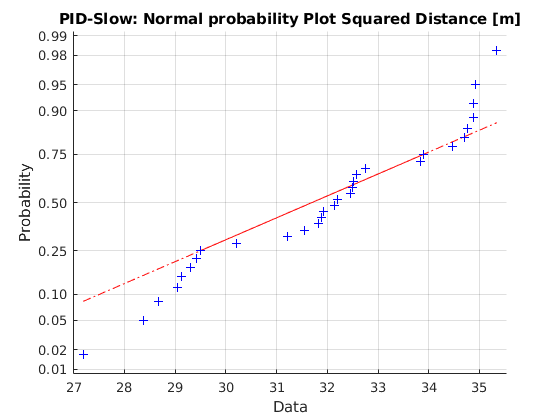

% Squared dist
figure(4)
normplot(pid_data_slow(:,1))
title('PID-Slow: Normal probability Plot Squared Distance [m]')

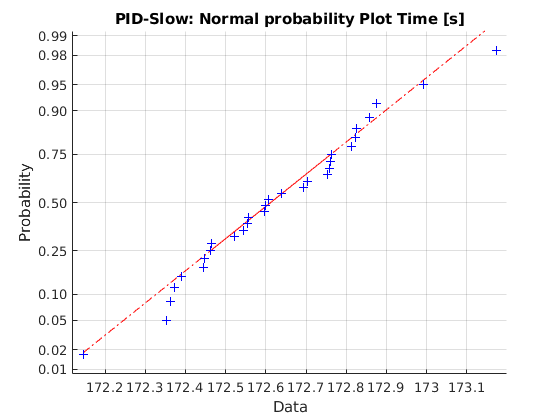


% Lap time 
figure(5)
normplot(pid_data_slow(:,2))
title('PID-Slow: Normal probability Plot Time [s]')

## PID Controller Fast

### Load data:

folder = 'eval_pid_fast'; %'../docker/ros-fence-inspection/assets/eval_pid';

pid_data_fast = load_n_process(folder);

### Normal distribution test:

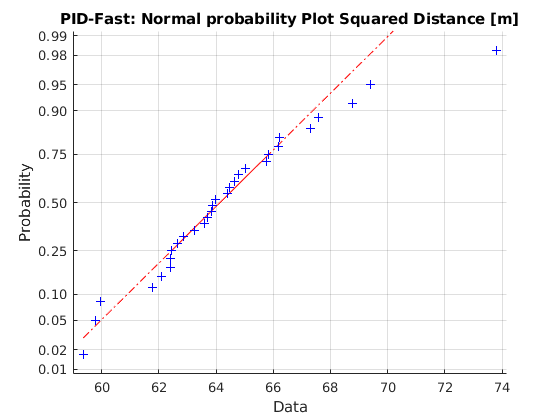

% Squared dist
figure(6)
normplot(pid_data_fast(:,1))
title('PID-Fast: Normal probability Plot Squared Distance [m]')

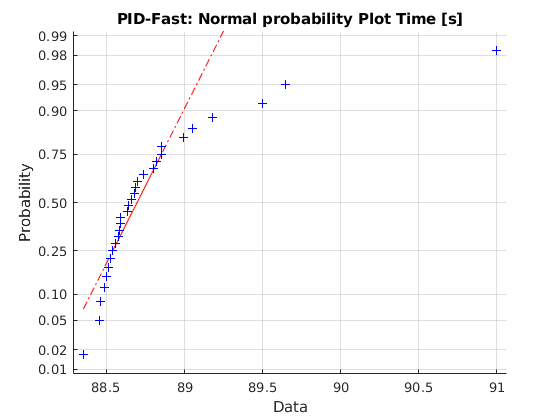


% Lap time 
figure(7)
normplot(pid_data_fast(:,2))
title('PID-Fast: Normal probability Plot Time [s]')

## Box plot

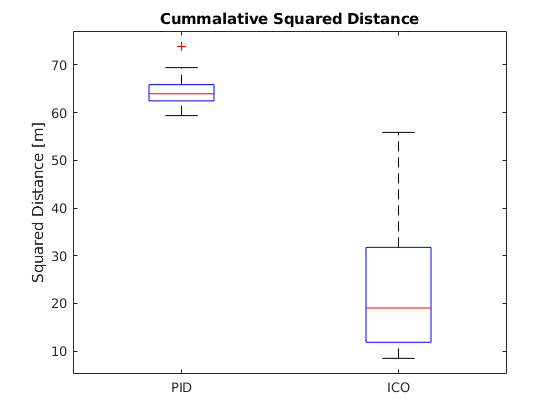

% Box plot for squared dist
figure(8)
boxplot([pid_data_fast(:,1), ico_data(:,1)],'Labels',{'PID','ICO'})
title('Cummalative Squared Distance')
ylabel('Squared Distance [m]')


% Box plot for lap time
figure(9)
boxplot([pid_data_fast(:,2), ico_data(:,2)],'Labels',{'PID','ICO'})

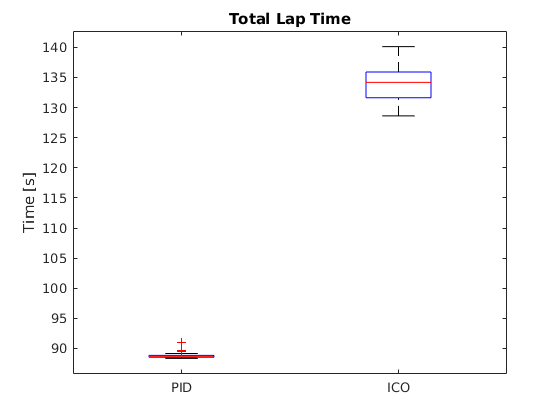

title('Total Lap Time')
ylabel('Time [s]')

## Equal variance test PID-Fast vs. ICO

In order to do a two-sample mean test the two samples must have equal variance.

[H, P] = vartest2(pid_data_fast, ico_data)

H =      1     1


P = 	1.0e+-11 *

    0.3940    0.0001


## Two sample Mean test between ICO and PID-Fast

[H, P] = ttest2(pid_data_fast, ico_data, 'Vartype','unequal')

H =      1     1


P = 	1.0e+-16 *

    0.1990    0.0000


# Comparation between fast and slow PID

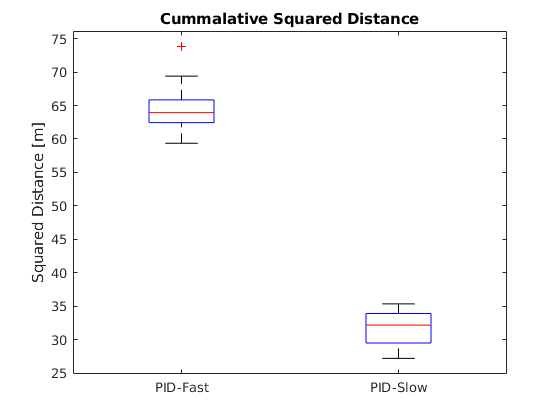

% Box plot for squared dist
figure(8)
boxplot([pid_data_fast(:,1), pid_data_slow(:,1)],'Labels',{'PID-Fast','PID-Slow'})
title('Cummalative Squared Distance')
ylabel('Squared Distance [m]')


% Box plot for lap time
figure(9)
boxplot([pid_data_fast(:,2), pid_data_slow(:,2)],'Labels',{'PID-Fast','PID-Slow'})

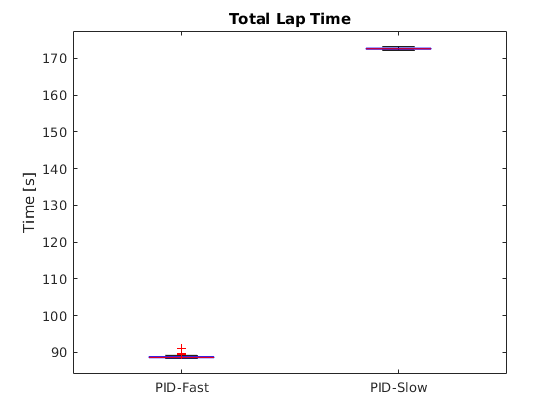

title('Total Lap Time')
ylabel('Time [s]')


[H, P] = vartest2(pid_data_fast, pid_data_slow)

H =      0     1


P =     0.1625    0.0000



% Equal variance on dist
[H, P] = ttest2(pid_data_fast(:,1), pid_data_slow(:,1), 'Vartype','equal')

H = 1

P = 7.6543e-48

% Unequal variance on time
[H, P] = ttest2(pid_data_fast(:,2), pid_data_slow(:,2), 'Vartype','unequal')

H = 1

P = 3.5454e-85

# Evaluation on airport map

ico_data = load_n_process('eval_ico_airport');
pid_data = load_n_process('eval_pid_airport');

## Functions

function data_list = load_n_process(folder)
% Loads the data from the folder and cummulates the squared error dist and calculate
% total time
    
    files = dir(fullfile(folder, '*.txt'));
    data_list = zeros(length(files), 2);
    
    for i = 1:length(files)
        data = load(append(files(i).folder,'/',files(i).name));
        data_list(i,1) = sum(data(:,1).^2);
        data_list(i,2) = data(end)- data(1,2);
    end
end